*Lab 7. Event selection optimization You and your lab partner should pick different pT (transverse momentum) samples (one uses low-pT sampels and the other use high-pT samples) for this lab. In each pT sample, there are dedicated training samples for event selection optimization. All studies should be carried out by normalizing Higgs and QCD samples in each pT sample to given expected yields accordingly (See Dataset descriptions).*

clear all; close all; clc;
tic;
h5disp("higgs_100000_pt_250_500.h5")

HDF5 higgs_100000_pt_250_500.h5 
Group '/' 
    Dataset 'higgs_100000_pt_250_500' 
        Size:  14x100000
        MaxSize:  14x100000
        Datatype:   H5T_IEEE_F64LE (double)
        ChunkSize:  []
        Filters:  none
        FillValue:  0.000000


higg1 = h5read("higgs_100000_pt_250_500.h5",'/higgs_100000_pt_250_500');
h5disp("higgs_100000_pt_250_500.h5")

HDF5 higgs_100000_pt_250_500.h5 
Group '/' 
    Dataset 'higgs_100000_pt_250_500' 
        Size:  14x100000
        MaxSize:  14x100000
        Datatype:   H5T_IEEE_F64LE (double)
        ChunkSize:  []
        Filters:  none
        FillValue:  0.000000


qcd1 = h5read("qcd_100000_pt_250_500.h5",'/qcd_100000_pt_250_500');

*Make a stacked histogram plot for the feature variable: mass*

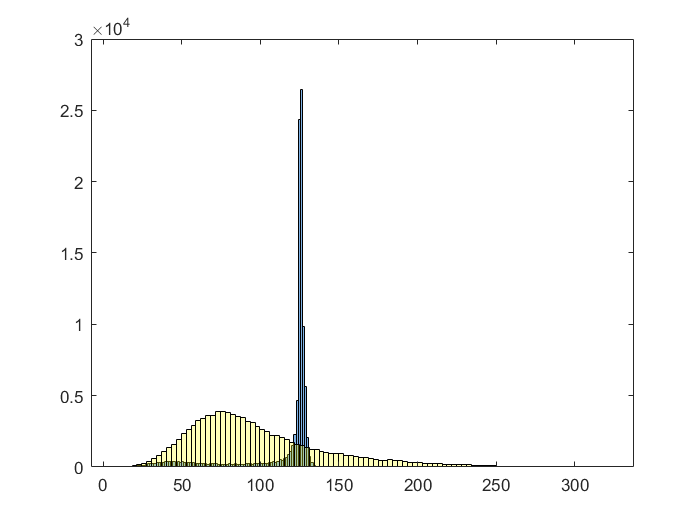

hInvariantMass = higg1(4,:);
histogram(hInvariantMass,100,'FaceColor',[0,.4,.8],'FaceAlpha',0.5)
hold on;
qInvariantMass = qcd1(4,:);
histogram(qInvariantMass,100,'FaceColor',[1,1,.1],'FaceAlpha',0.3)
hold off;

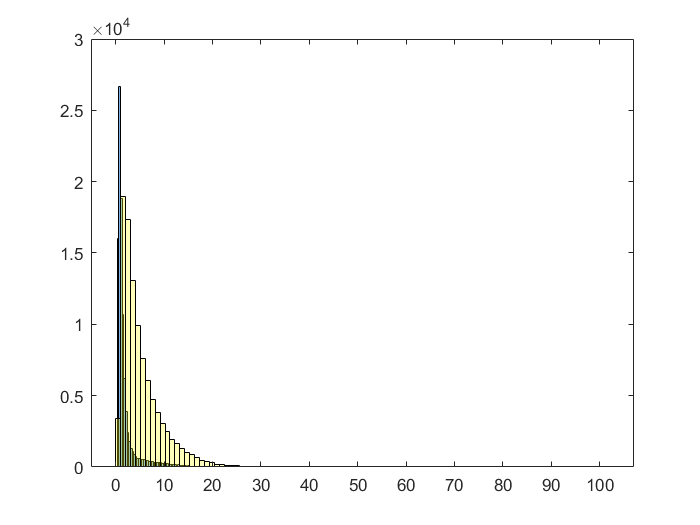

h3to2pointECFratio = higg1(7,:);
histogram(h3to2pointECFratio,100,'FaceColor',[0,.4,.8],'FaceAlpha',0.5)
hold on;
q3to2pointECFratio = qcd1(7,:);
histogram(q3to2pointECFratio,100,'FaceColor',[1,1,.1],'FaceAlpha',0.3)
hold off;

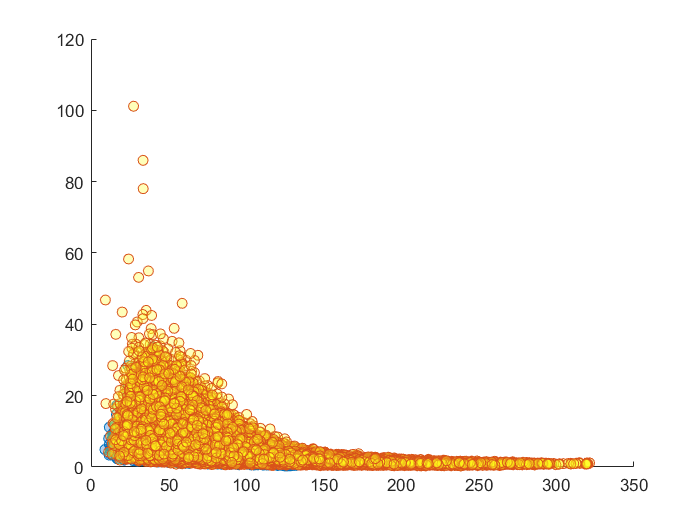

clf;
hold on;
scatter(hInvariantMass,h3to2pointECFratio,'MarkerFaceColor',[0,.4,.8],'MarkerFaceAlpha',0.3)
scatter(qInvariantMass,q3to2pointECFratio,'MarkerFaceColor',[1,1,.1],'MarkerFaceAlpha',0.3)
hold off;

- *Evaluate expected significance without any event selection.*

- *Use Poisson statistics for significance calculation*

- *Compare your number of NHiggs/√(NQCD). If they are equivalent, explain your findings.*

NHiggs/√(NQCD) is not equivalent, therefore explanations of my findings are not required. :)

nHiggs = 100;
nQCD = 2000;
comp3 = nHiggs/sqrt(nQCD)

comp3 = 2.2361

hInvarDist=fitdist(hInvariantMass',"Poisson");
hInvarDistLambda = round(median(hInvariantMass)) %eyeballing lambda due to innacuracy in distribution created since it doesnt exactly follow a poisson distribution.

hInvarDistLambda = 125

qInvariantMassLambda = 75 %eyeballing lambda due to innacuracy in distribution created since it doesnt exactly follow a poisson distribution.

qInvariantMassLambda = 75

Make stacked histogram plots for the reset of features

- Set A of plots without any event selection

- Can you identify another feature as discriminative as mass feature (i.e. equal or better significance after feature cut)

Comparing Higgs data (in blue) with QCD data (in yellow)

**Transverse momentum:**

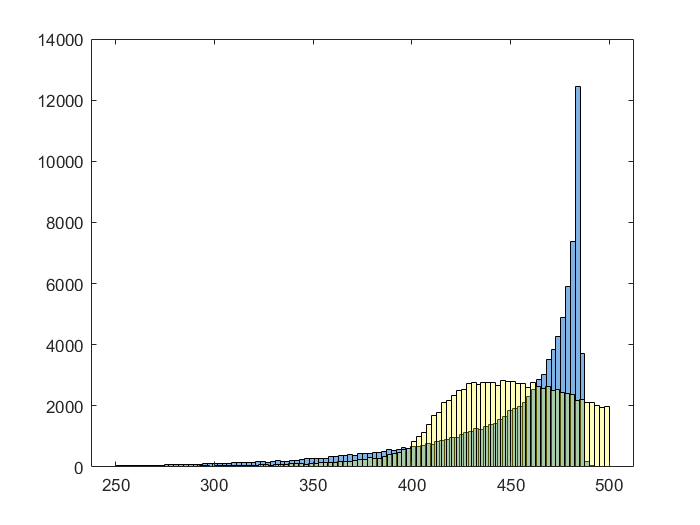

hTransverseMomentum = higg1(1,:);
histogram(hTransverseMomentum,100,'FaceColor',[0,.4,.8],'FaceAlpha',0.5)
hold on;
qTransverseMomentum = qcd1(1,:);
histogram(qTransverseMomentum,100,'FaceColor',[1,1,.1],'FaceAlpha',0.3)
hold off; 

hTransverseMomentumDist=fitdist(higg1(1,:)',"Poisson");
qTransverseMomentumDist=fitdist(qcd1(1,:)',"Poisson");

hTransverseMomentumDist=fitdist(hInvariantMass',"Poisson");
hTransverseMomentumDistLambda = 446

hTransverseMomentumDistLambda = 446

qTransverseMomentumLambda = 483

qTransverseMomentumLambda = 483

t = 1;
funct = @(t) (100*(cdf(hTransverseMomentumDist,hTransverseMomentumDistLambda-t)-cdf(qTransverseMomentumDist, qTransverseMomentumLambda-t)))/(sqrt(20000*abs(cdf(qTransverseMomentumDist,qTransverseMomentumLambda-t)-cdf(qTransverseMomentumDist,qTransverseMomentumLambda+t))));
clear currentRatio;
currentRatio = funct(t);

for t = 2:0.000001:100
    difference = abs(funct(t)-currentRatio);
    currentRatio = funct(t);
    if difference<0.0000001
        cut = t;
        break
    end
end
cut

cut = 2.0000

currentRatio 

currentRatio = 0.2553

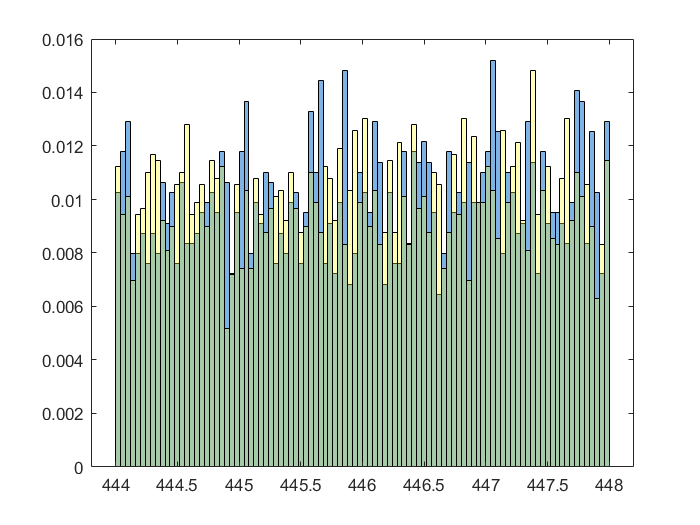

hTransverseMomentum(hTransverseMomentum<hTransverseMomentumDistLambda-cut) = [];
hTransverseMomentum(hTransverseMomentum>hTransverseMomentumDistLambda+cut) = [];
qTransverseMomentum(qTransverseMomentum<hTransverseMomentumDistLambda-cut) = [];
qTransverseMomentum(qTransverseMomentum>hTransverseMomentumDistLambda+cut) = [];

histogram(hTransverseMomentum,100,"Normalization", "Probability",'FaceColor',[0,.4,.8],'FaceAlpha',0.5)
hold on;
histogram(qTransverseMomentum,100,"Normalization", "Probability",'FaceColor',[1,1,.1],'FaceAlpha',0.3)
hold off;

**Pseudorapidity**

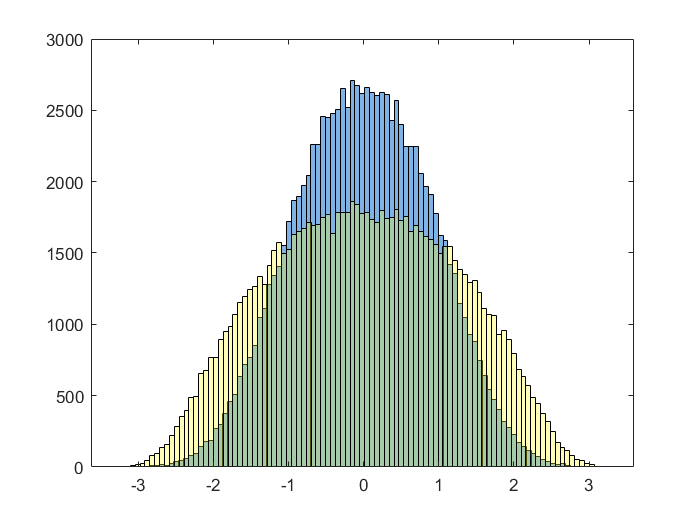

hPseudorapidity = higg1(2,:);
histogram(hPseudorapidity,100,'FaceColor',[0,.4,.8],'FaceAlpha',0.5)
hold on;
qPseudorapidity = qcd1(2,:);
histogram(qPseudorapidity,100,'FaceColor',[1,1,.1],'FaceAlpha',0.3)
hold off;

**Azimuthal angle**

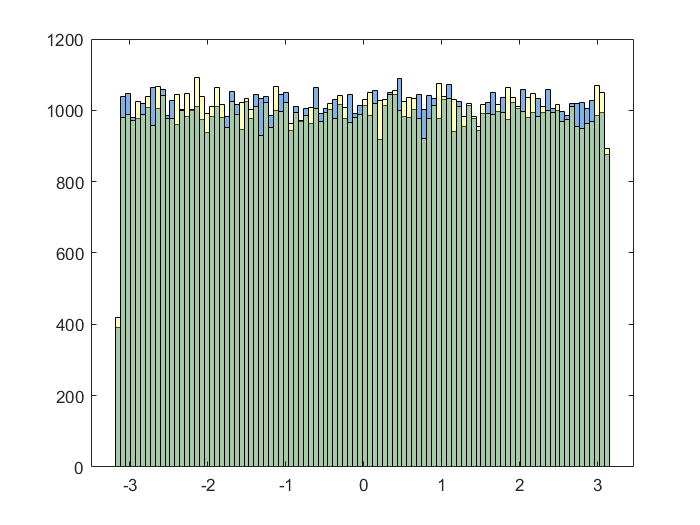

hAzimuthAngle = higg1(3,:);
histogram(hAzimuthAngle,100,'FaceColor',[0,.4,.8],'FaceAlpha',0.5)
hold on;
qAzimuthAngle = qcd1(3,:);
histogram(qAzimuthAngle,100,'FaceColor',[1,1,.1],'FaceAlpha',0.3)
hold off;

**Invariant masses**

hInvariantMass = higg1(4,:);
histogram(hInvariantMass,100,'FaceColor',[0,.4,.8],'FaceAlpha',0.5)
hold on;
qInvariantMass = qcd1(4,:);
histogram(qInvariantMass,100,'FaceColor',[1,1,.1],'FaceAlpha',0.3)
hold off;

ratio = 222.3626

cut = 6.5000

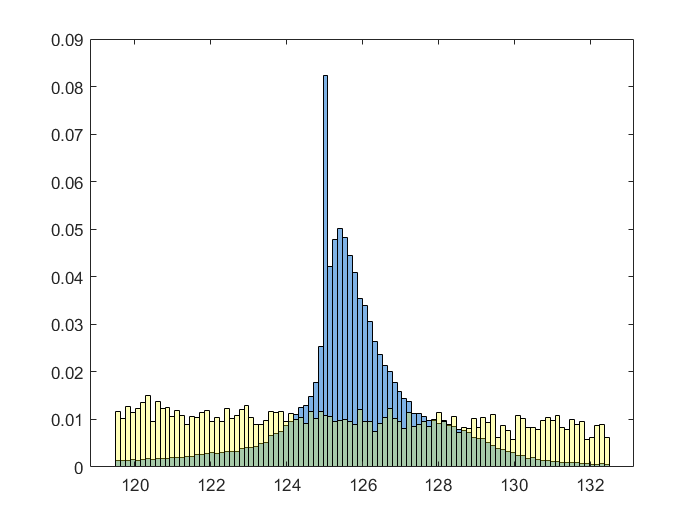

[ratios, cut, hCut1, qCut1] = massCut3(hInvariantMass,qInvariantMass,126,75);

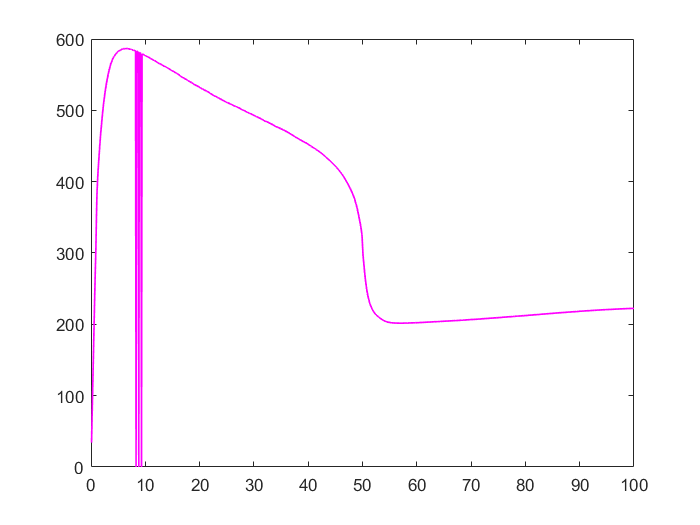

x = 0.1:0.1:100;
plot(x,ratios,"Linewidth", 1, "Color",[1 0 1])

ratio = 700.0783

cut = 1.7000

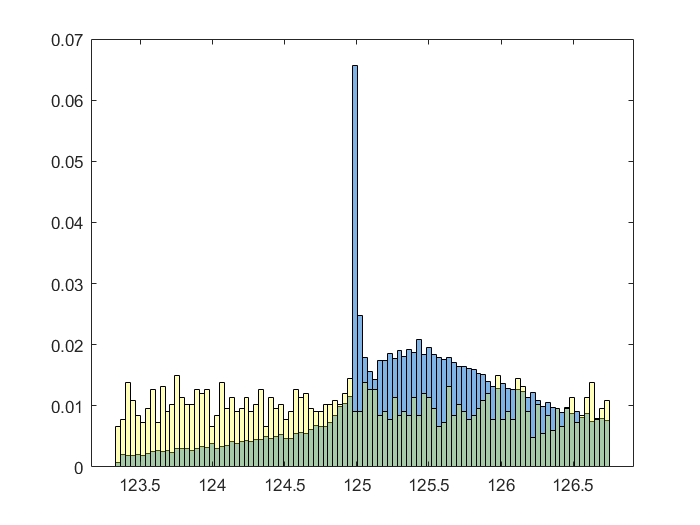

[ratios, cut, hCut2, qCut2] = massCut3(hCut1,qCut1,125.05,120.35);

hInvarAvg = mean(hInvariantMass)

hInvarAvg = 114.8924

hInvarSTD = std(hInvariantMass)

hInvarSTD = 25.3511

qInvarAvg = mean(qInvariantMass)

qInvarAvg = 97.7380

qInvarSTD = std(qInvariantMass)

qInvarSTD = 43.4929

STD is large and skewed due to some higgs picked up on the left side of the graph, and this distribution is not a normal distribution so the STD is not very useful. 

Using the range of 120-132 which is where the spike appears to be, we created a list of the indices of the QCD data points where that mass range is within that spike.

newIndex(1) = 0;
newLength = 1;
for i=1:length(qInvariantMass)
    if (qInvariantMass(i) > 120 && qInvariantMass(i) < 132)
        newIndex(newLength) = i;
        newLength = newLength +1;
    end
end

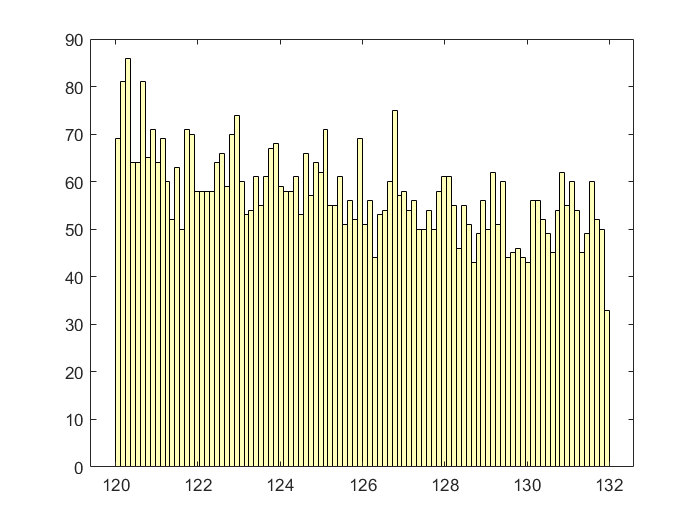

newQInvariantMass = qInvariantMass(newIndex);
histogram(newQInvariantMass,100,'FaceColor',[1,1,.1],'FaceAlpha',0.3)

**2 point ECF ratio (2PECFR)**

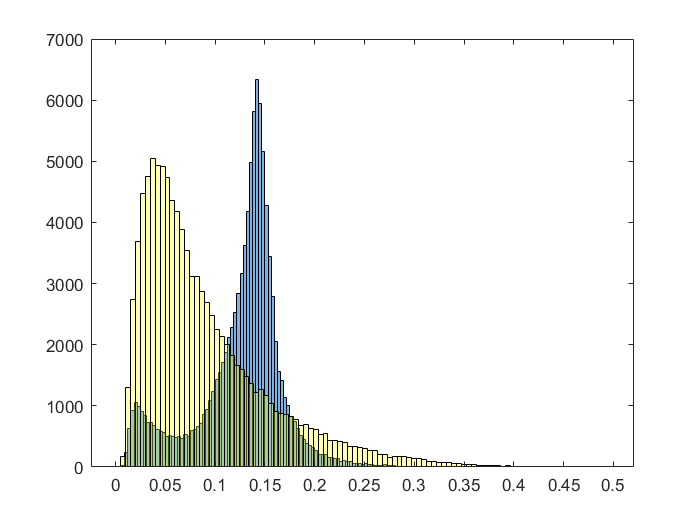

h2PointECFratio = higg1(5,:);
histogram(h2PointECFratio,100,'FaceColor',[0,.4,.8],'FaceAlpha',0.5)
hold on;
q2PointECFratio = qcd1(5,:);
histogram(q2PointECFratio,100,'FaceColor',[1,1,.1],'FaceAlpha',0.3)
hold off;

ratio = 223.5677

cut = 0.3000

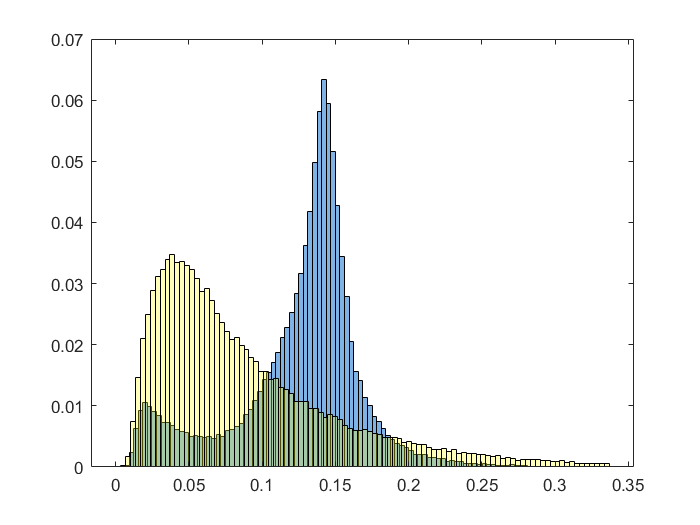

massCut3(h2PointECFratio,q2PointECFratio,0.037,0.141);

**3 point ECF ratio (3PECFR)**

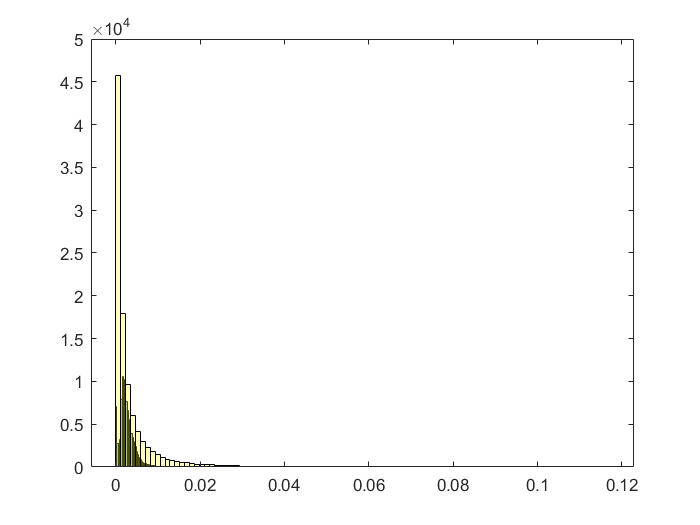

h3PointECFratio = higg1(6,:);
histogram(h3PointECFratio,100,'FaceColor',[0,.4,.8],'FaceAlpha',0.5)
hold on;
q3PointECFratio = qcd1(6,:);
histogram(q3PointECFratio,100,'FaceColor',[1,1,.1],'FaceAlpha',0.3)
hold off;

**3 to 2 point ECF ratio (3-2PECFR)**

h3to2pointECFratio = higg1(7,:);
histogram(h3to2pointECFratio,100,'FaceColor',[0,.4,.8],'FaceAlpha',0.5)
hold on;
q3to2pointECFratio = qcd1(7,:);
histogram(q3to2pointECFratio,100,'FaceColor',[1,1,.1],'FaceAlpha',0.3)
hold off;

**Angularity:**

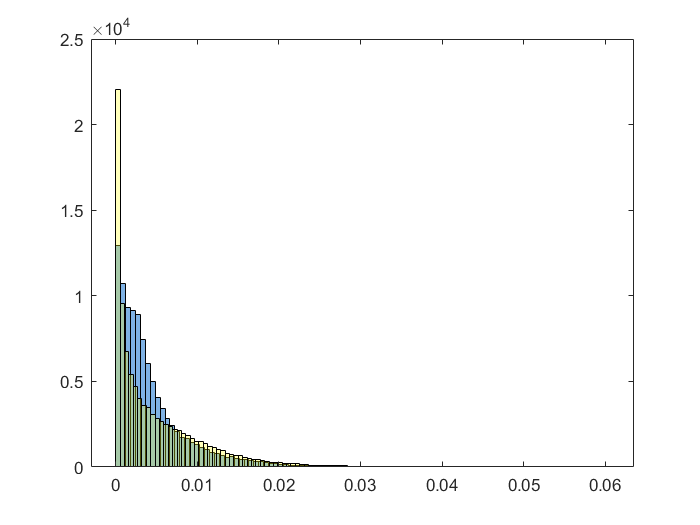

hAngularity = higg1(8,:);
histogram(hAngularity,100,'FaceColor',[0,.4,.8],'FaceAlpha',0.5)
hold on;
qAngularity = qcd1(8,:);
histogram(qAngularity,100,'FaceColor',[1,1,.1],'FaceAlpha',0.3)
hold off;

**Variable 9:**

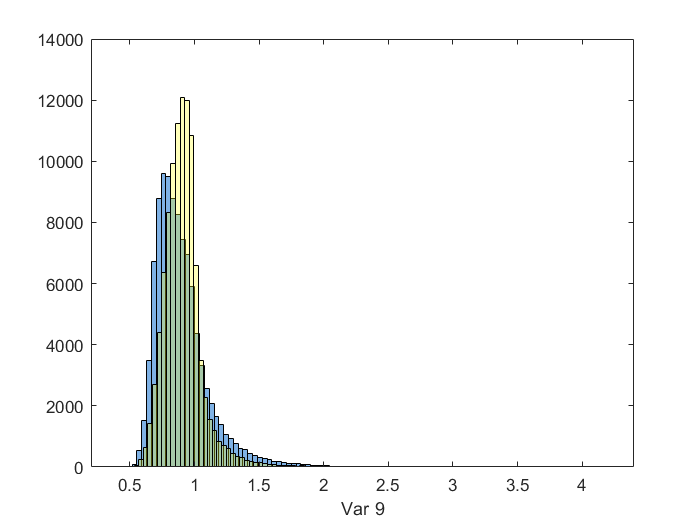

hvar9 = higg1(9,:);
histogram(hvar9,100,'FaceColor',[0,.4,.8],'FaceAlpha',0.5)
xlabel 'Var 9'
hold on
qvar9 = qcd1(9,:);
histogram(qvar9,100,'FaceColor',[1,1,.1],'FaceAlpha',0.3)
hold off

**Variable 10**

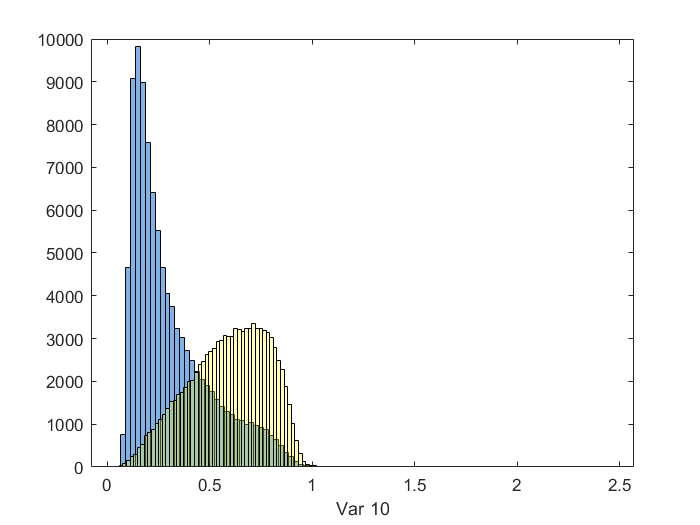

hvar10 = higg1(10,:);
histogram(hvar10,100,'FaceColor',[0,.4,.8],'FaceAlpha',0.5)
xlabel 'Var 10'
hold on
qvar10 = qcd1(10,:);
histogram(qvar10,100,'FaceColor',[1,1,.1],'FaceAlpha',0.3)
hold off

**Variable 11**

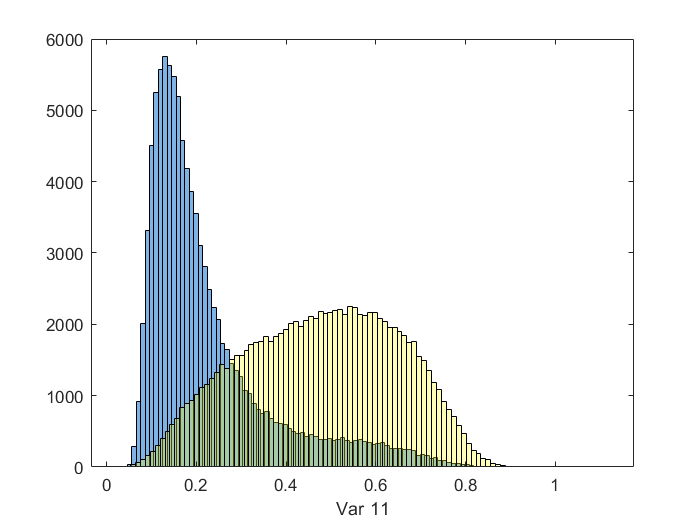

hvar11 = higg1(11,:);
histogram(hvar11,100,'FaceColor',[0,.4,.8],'FaceAlpha',0.5)
xlabel 'Var 11'
hold on
qvar11 = qcd1(11,:);
histogram(qvar11,100,'FaceColor',[1,1,.1],'FaceAlpha',0.3)
hold off

ratio = 223.5677

cut = 0.5000

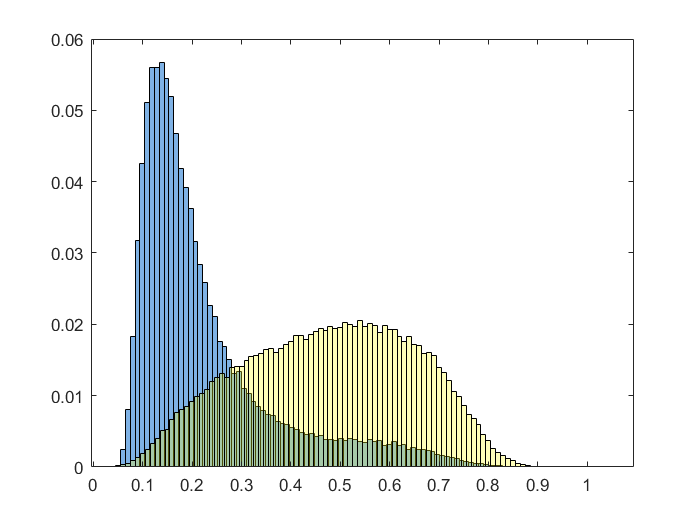

massCut3(hvar11,qvar11,0.55,0.15);

**Variable 12**

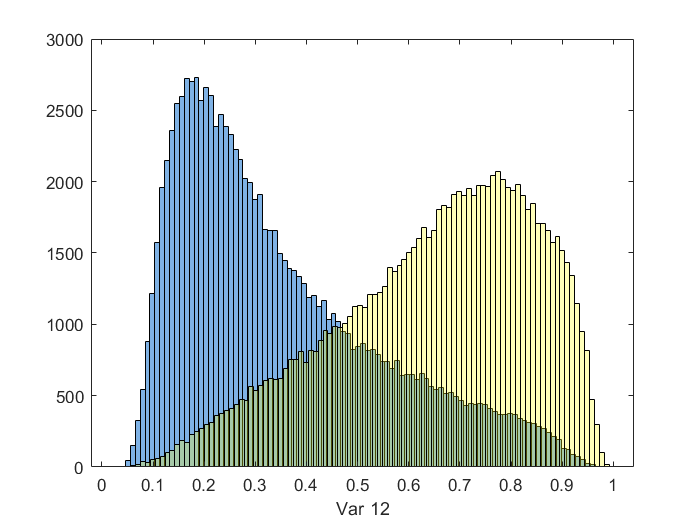

hvar12 = higg1(12,:);
histogram(hvar12,100,'FaceColor',[0,.4,.8],'FaceAlpha',0.5)
xlabel 'Var 12'
hold on
qvar12 = qcd1(12,:);
histogram(qvar12,100,'FaceColor',[1,1,.1],'FaceAlpha',0.3)
hold off

**Variable 13**

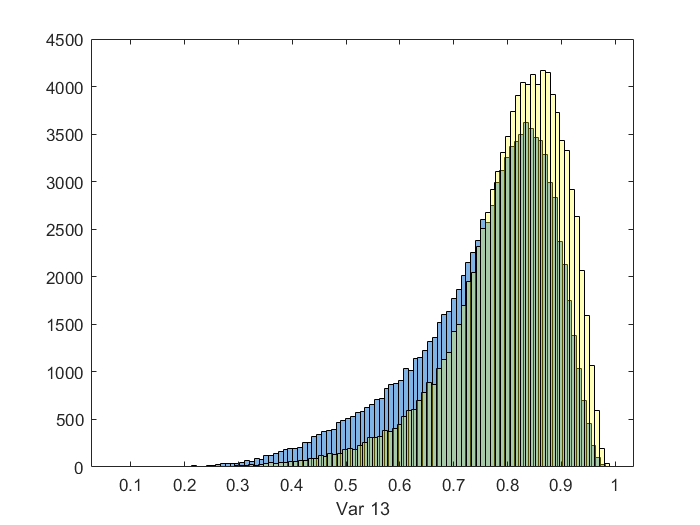

hvar13 = higg1(13,:);
histogram(hvar13,100,'FaceColor',[0,.4,.8],'FaceAlpha',0.5)
xlabel 'Var 13'
hold on
qvar13 = qcd1(13,:);
histogram(qvar13,100,'FaceColor',[1,1,.1],'FaceAlpha',0.3)
hold off

**Variable 14**

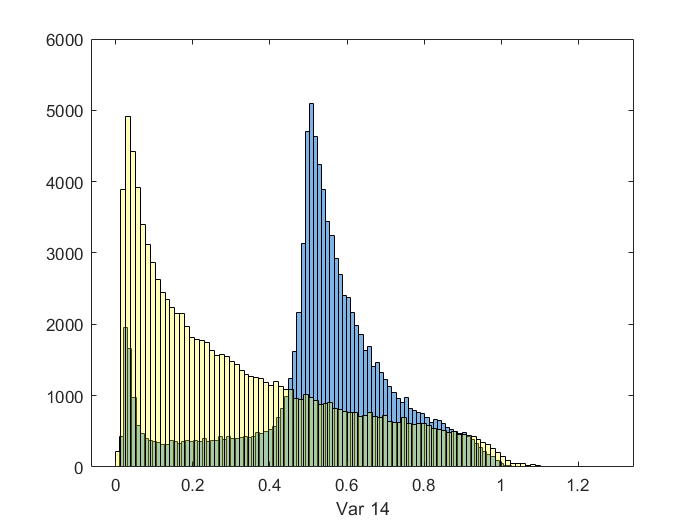

hvar14 = higg1(14,:);
histogram(hvar14,100,'FaceColor',[0,.4,.8],'FaceAlpha',0.5)
xlabel 'Var 14'
hold on
qvar14 = qcd1(14,:);
histogram(qvar14,100,'FaceColor',[1,1,.1],'FaceAlpha',0.3)
hold off

toc;

Elapsed time is 16.284657 seconds.
